# Neuron Coverage for Deep Learning Network

This example shows how to compute neuron coverage for an image classification network.

Neuron coverage is a metric for measuring the parts of a network activated by a particular set of test data. This example computes the neuron coverage using `neuronCoverage`, this implementation of neuron coverage is based on the DeepXplore framework [1]. 

A neuron is *activated* if, after rescaling and spatial averaging, the absolute value of the neuron is greater than the *activation threshold* for at least one observation in the test data. The neuron coverage of a layer is then the fraction of activated neurons. For more information, see the Algorithms section in `doc\neuronCoverage.md`.

## Load Data

Load the digit sample data as an image datastore. The digits data set consists of synthetic grayscale images of handwritten digits. Each image is 28-by-28 pixels and has an associated label denoting which digit the image represents (0–9).

rng("default")
digitDatasetPath = fullfile(matlabroot,"toolbox","nnet","nndemos", ...
    "nndatasets","DigitDataset");

imds = imageDatastore(digitDatasetPath, ...
    IncludeSubfolders=true,LabelSource="foldernames");

Divide the data into training, validation, and test data sets.

- Training data—Contains 750 images from each class. Use this data to update the learnable parameters during training.

- Validation data—Contains 225 images from each class. Use this data to evaluate network performance during training. 

- Test data—Contains 25 images from each class. Use this data to provide an unbiased assessment of network performance after training and to compute the neuron coverage.

numTrainFiles = 750;
numValidationFiles = 225;
numTestFiles = 1000 - numTrainFiles - numValidationFiles;

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,numTrainFiles,numValidationFiles,"randomize");

## Define Network Architecture

Define the convolutional neural network architecture. Specify the size of the images in the input layer of the network and the number of classes in the fully connected layer before the classification layer. Each image is 28-by-28-by-1 pixels and there are 10 classes.

inputSize = [28 28 1];
numClasses = 10;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer(Name="relu")
    fullyConnectedLayer(numClasses,Name="fc")
    softmaxLayer(Name="softmax")
    classificationLayer];

## Specify Training Options

Specify the training options.

- Train the network using SGDM.

- Train using an initial learning rate of 0.01.

- Train for 5 epochs.

- Shuffle the data every epoch.

- Monitor the network accuracy during training by specifying validation data.

- Display the training progress in a plot and suppress the verbose command window output.

The software trains the network on the training data and calculates the accuracy on the validation data at regular intervals during training. The validation data is not used to update the network weights. By default, `trainNetwork` uses a GPU if one is available, otherwise, it uses a CPU. Training on a GPU requires Parallel Computing Toolbox™ and a supported GPU device. You can also specify the execution environment by using the `ExecutionEnvironment` name-value pair argument of `trainingOptions`. For this example, set `ExecutionEnvironment` to `"cpu"`.

options = trainingOptions("sgdm", ...
    InitialLearnRate=0.01, ...
    MaxEpochs=5, ...
    Shuffle="every-epoch", ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Verbose=false, ...
    Plots="training-progress", ...
    ExecutionEnvironment="cpu");

## Train Network

Train the network using the architecture defined by `layers`, the training data, and the training options.

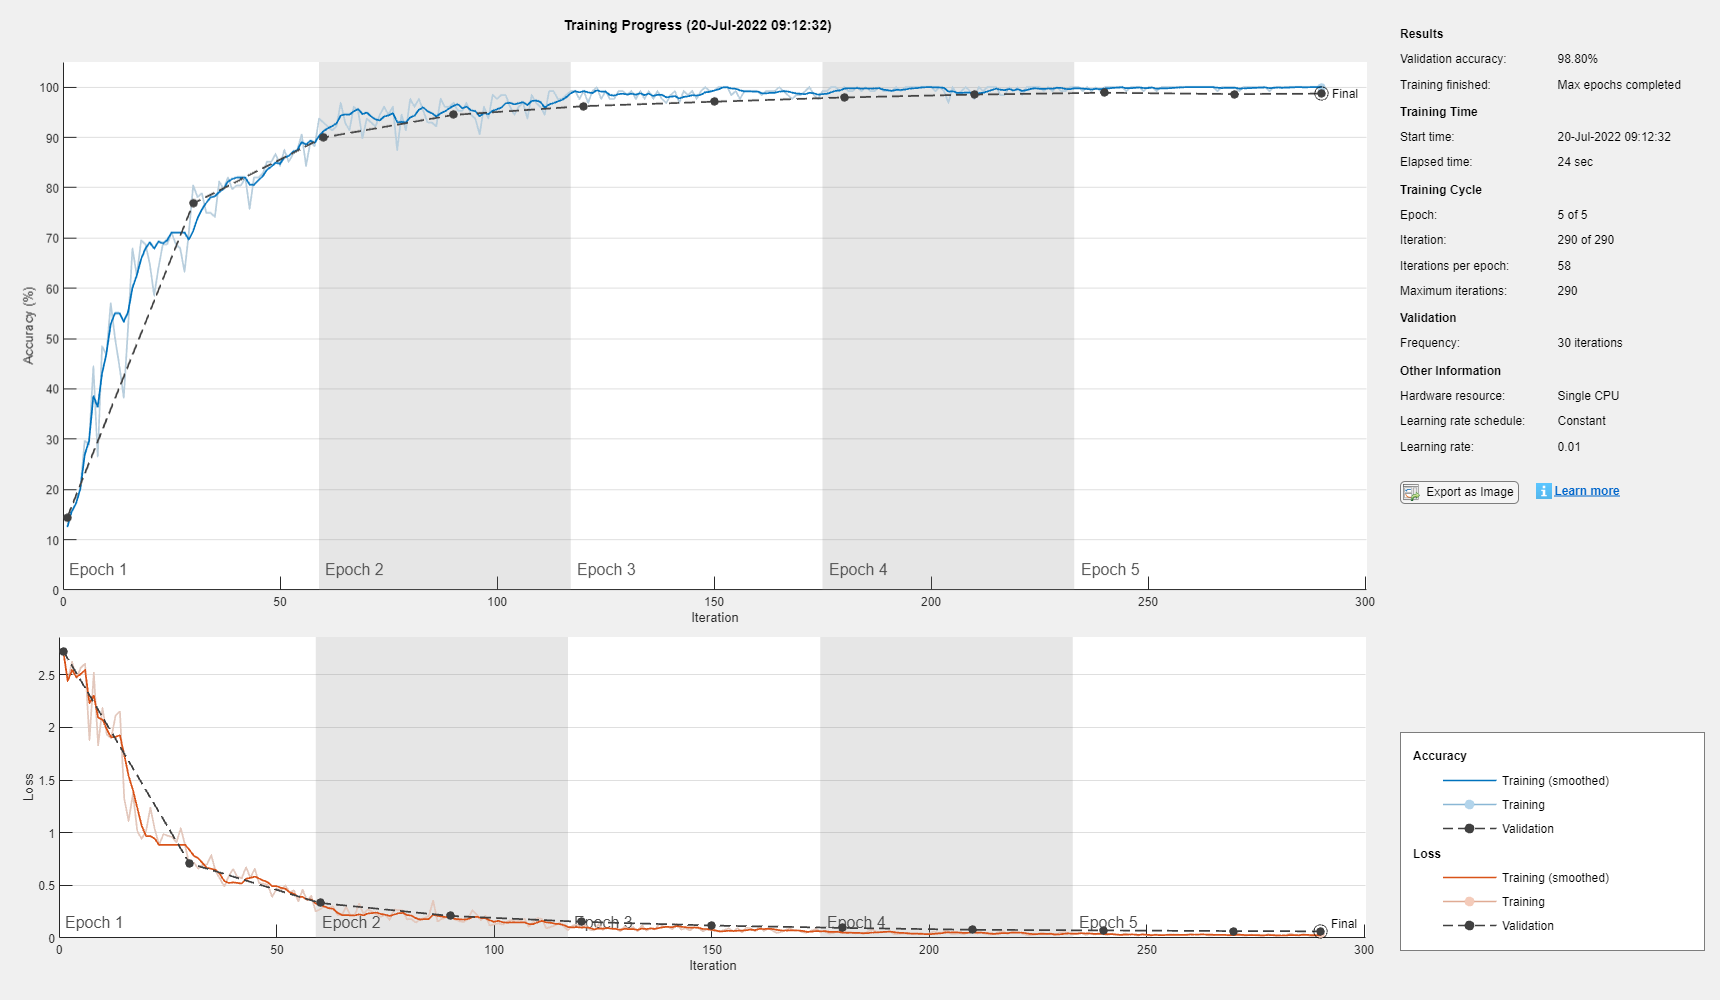

net = trainNetwork(imdsTrain,layers,options);

## Test Network

Predict the labels of the test data using the trained network and calculate the accuracy. 

YPred = classify(net,imdsTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9840

## Assess Neuron Coverage on Test Data

To compute the neuron coverage, you must convert the network to a `dlnetwork` object and the data to a `dlarray` object.

Remove the output layer and convert the network to a `dlnetwork` object. 

lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,"classoutput");

net = dlnetwork(lgraph);

Create a `minibatchqueue` object containing the test data. `minibatchqueue` objects automatically convert your data to `dlarray`. This data is not shuffled, therefore, as the test set contains 25 images from each class, images 1–25 are from class "0", images 26–50 are from class "1", and so on. Set `MiniBatchSize` to equal `numTestFiles` so that each batch contains one of the ten classes. The images are single-channel black-and-white images. Add a singleton channel dimension by applying the format `"SSBC"` to the batch. 

miniBatchSize = numTestFiles;
mbq = minibatchqueue(imdsTest, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFormat="SSBC");

Compute the neuron coverage for the first batch of test data. This batch contains images from class "0".

subsetZeroes = next(mbq);
subsetZeroesPred = YPred(1:numTestFiles);

Plot the images and their predictions.

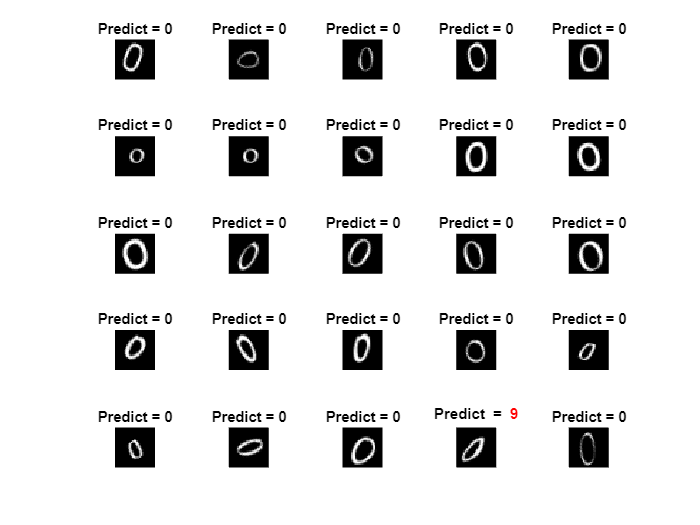

figure
tiledlayout("flow")

for i = 1:numTestFiles
    nexttile
    imshow(uint8(extractdata(subsetZeroes(:,:,:,i))));
    if subsetZeroesPred(i) ~= "0"
            title("Predict = " + "\color{red}" + string(subsetZeroesPred(i)))
    else 
            title("Predict = " + string(subsetZeroesPred(i)))
    end
end

Create a `neuronCoverage` object using the set of images from class "0". Find the neuron coverage for the ReLU, fully connected, and softmax layers. Specify a threshold of 0.9. The threshold (also known as *activation threshold*) sets the cutoff above which a neuron is considered *activated*.

threshold = 0.9;
nc = neuronCoverage(net,threshold, ...
    LayerNames=["relu","fc","softmax"], ...
    Data=subsetZeroes)

nc =   neuronCoverage with properties:

              Network: [1×1 dlnetwork]
            Threshold: 0.9000
           LayerNames: ["relu"    "fc"    "softmax"]
        LayerCoverage: [3×1 table]
    AggregateCoverage: 0.1250


The `neuronCoverage` object contains the neuron coverage for each of the specified layers and the aggregate coverage across those layers. View the neuron coverage for the three layers.

nc.LayerCoverage

ans = 3×1 table
               LayerCoverage
               _____________

    relu              0     
    fc              0.3     
    softmax         0.2     


The ReLU layer has a neuron coverage of 0, this means that none of the neurons in the ReLU layer exceed the activation threshold of 0.9. The softmax layer contains ten neurons, one for each of the ten classes. In the first mini-batch of images, 24 images are correctly classified as "0" and a single image is misclassified as "9". Therefore, the test data is activating the softmax layer for two out of the ten neurons. This highlights that neuron coverage is not directly related to accuracy as 100% accuracy on this mini-batch will result in a lower neuron coverage in the softmax layer. 

### Add More Test Data

The neuron coverage increases as you add images with increasing diversity. Add the next mini-batch containing images from class "1". Each time you add more data, the `neuronCoverage` object updates to return the layer coverage using all of the test data added so far.

subsetOnes = next(mbq);
subsetOnesPred = YPred(numTestFiles:(numTestFiles*2-1));

Plot the images from class "1".

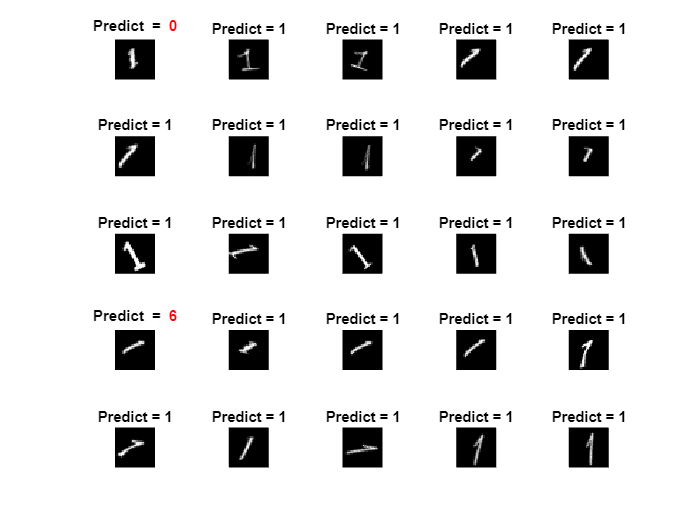

figure
tiledlayout("flow")

for i = 1:numTestFiles
    nexttile
    imshow(uint8(extractdata(subsetOnes(:,:,:,i))));
    if subsetOnesPred(i) ~= "1"
            title("Predict = " + "\color{red}" + string(subsetOnesPred(i)))
    else 
            title("Predict = " + string(subsetOnesPred(i)))
    end
end

Add the data from class "1" to the neuron coverage object.

nc = addData(nc,subsetOnes);
nc.LayerCoverage

ans = 3×1 table
               LayerCoverage
               _____________

    relu              0     
    fc              0.5     
    softmax         0.4     


The coverage of the softmax and fully connected layers increases as the test set has been diversified. The sample of ones in the 25 images are classified as either "0", "1", or "6". This increases the softmax neuron coverage to include the neurons corresponding to "1" and "6", therefore, the neuron coverage of the softmax layer increases from 20% to 40%.

### Add All Test Data

To see how the coverage changes as each batch is added, reset the `neuronCoverage` object and add all of the test images.

Reset the `minibatchqueue` object.

reset(mbq)

Reset the data information in the `neuronCoverage` object.

nc = resetData(nc);

Add each mini-batch to the `neuronCoverage` object. Each minibatch corresponds to one of the ten classes.

coveragembq = [];
batch = 0;
while hasdata(mbq)
    batch = batch + 1;
    testData = next(mbq);

    nc = addData(nc,testData);
    coveragembq(:,batch) = getCoverageForLayer(nc,["relu", "fc","softmax"]);
end

Plot the results.

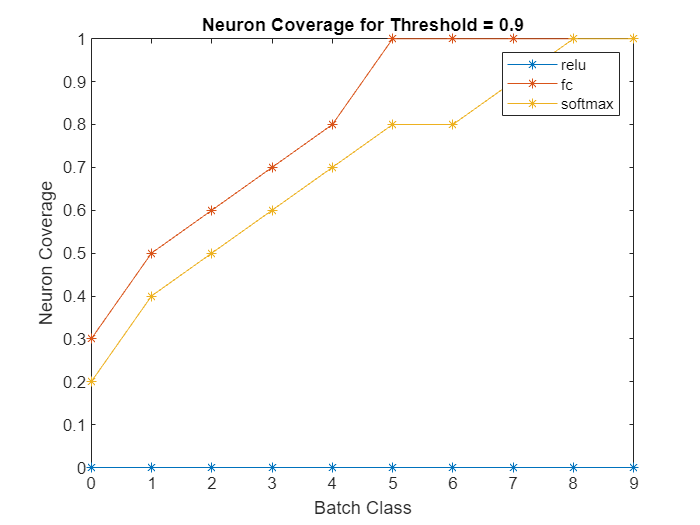

figure
plot(0:(numClasses-1),coveragembq,"-*")

legend(["relu", "fc","softmax"])
xlabel("Batch Class")
ylabel("Neuron Coverage")
title("Neuron Coverage for Threshold = " + nc.Threshold)

As the different classes are added to the neuron coverage calculation, the coverage of the fully connected and softmax layers increases. Once all of the test data has been added, the coverage for the fully connected and softmax layers is 100%. The coverage for the ReLU layer remains at 0%, even when all of the test data has been added. This is likely due to the threshold being high.

## Change Threshold Value

Investigate how changing the threshold value impacts the neuron coverage.  

Compute the neuron coverage for a range of activation thresholds. A lower threshold means more neurons will be classified as activated.

totalCoverage = [];
coverage = [];

thresholdValues = 0:0.1:1;

for i = 1:numel(thresholdValues)
    nc.Threshold = thresholdValues(i);
    coverage(:,i) = getCoverageForLayer(nc,["relu", "fc","softmax"]);
    totalCoverage(i) = nc.AggregateCoverage;
end

nc.Threshold = threshold; 

Plot the results.

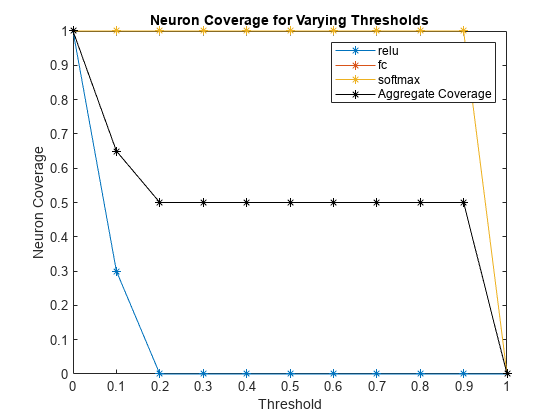

figure
plot(thresholdValues,coverage,"*-")
hold on 
plot(thresholdValues,totalCoverage,"k*-")
legend(["relu", "fc","softmax","Aggregate Coverage"])
xlabel("Threshold")
ylabel("Neuron Coverage")
title("Neuron Coverage for Varying Thresholds")

In this example, the fully connected and softmax layers have the same coverage across the varying thresholds. When the threshold is 0.1, the ReLU layer still only achieves a neuron coverage of 0.3. To better understand these values, analyze the network.

analyzeNetwork(net)

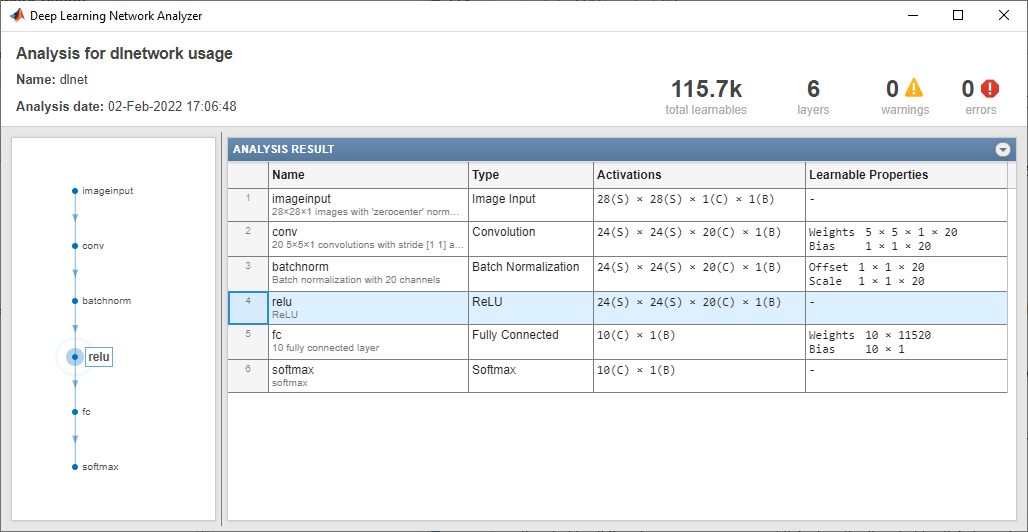

The ReLU layer has an output size of 24-by-24-by-20, where 24-by-24 is the size of the feature map and 20 is the number of channels. Neuron coverage averages over all spatial dimensions, therefore, the coverage is computed with respect to the 20 averaged neurons in the ReLU layer. A neuron coverage of 0.3 means that six neurons in the ReLU layer are considered activated when the threshold is 0.1. 

### Investigate Low Neuron Coverage

To compute the neuron coverage, the neurons are rescaled so that they lie between 0 and 1 and then averaged across all spatial dimensions (for more information, see the Algorithms section in `doc\neuronCoverage.md`). In this example, the images are mostly black pixels, therefore, averaging across the spatial dimensions will bias the neurons towards 0 (black). As a result, even with all of the test data, the activation threshold needs to be very low for the neurons in the ReLU layer to be considered activated. For neurons in layers with nonsingleton spatial or time dimensions to be activated, you may need to use a lower threshold value. 

Another way to increase the neuron coverage is to diversify your test data. Invert the first test image so that it is now a black digit on a white background.

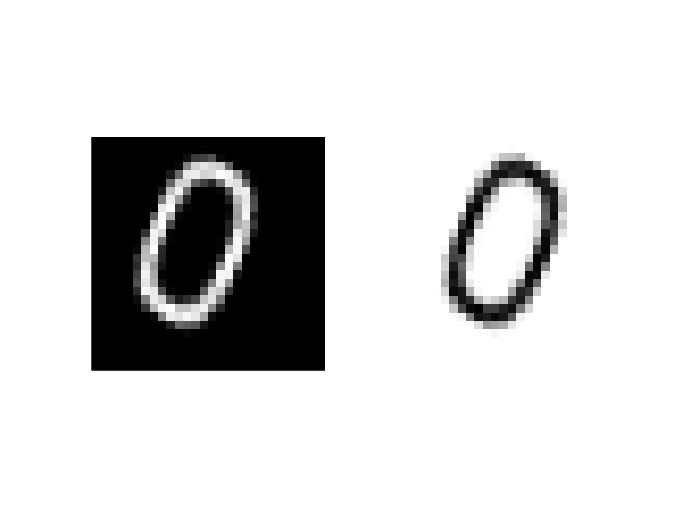

img = read(imdsTest);
XNew = 255 - img;

figure 
subplot(1,2,1) 
imshow(img)
subplot(1,2,2) 
imshow(XNew)

Set the activation threshold to 0.5. Add the new image to the `neuronCoverage` object. Compare the neuron coverage of the ReLU layer before and after adding additional image.

nc.Threshold = 0.5;
getCoverageForLayer(nc,"relu")

ans = 0

nc = addData(nc,dlarray(double(XNew),"SSCB"));
getCoverageForLayer(nc,"relu")

ans = 0.0500

The coverage for the ReLU layer increases from 0 to 0.05 when the threshold is 0.5. This corresponds to a single neuron in the ReLU layer now being activated by the inverted image. However, this does not imply that the network can correctly classify images of this type. To classify inverted images, you need to augment your training data to include correctly labelled inverted images and retrain the network.

## References

[1] Pei, Kexin, Yinzhi Cao, Junfeng Yang, and Suman Jana. “DeepXplore: Automated Whitebox Testing of Deep Learning Systems.” *GetMobile: Mobile Computing and Communications* 22, no. 3 (January 17, 2019): 36–38. https://doi.org/10.1145/3308755.3308767.

*Copyright 2022 The MathWorks, Inc.*